# **Planning and Navigation**

For a mobile robot, the cognitive capability most directly linked to robust mobility is navigation competence. Given partial knowledge of its environment and a goal position (or a sequence of goal positions), navigation encompasses the robot’s ability to act based on its knowledge and sensor observations so as to reach its goals efficiently and reliably. 

## Planning and Reacting

Within artificial intelligence, planning and reacting are sometimes viewed as opposing paradigms. However, when applied to physical systems such as mobile robots, the two are highly complementary, each is essential for successful navigation. A robot must:

- **Plan** a course of action to reach a goal, and

- **React** to unforeseen events during execution to ensure the plan remains achievable.

Without reactive behavior, even a perfect plan may fail due to unmodelled obstacles or dynamic environmental changes. Without planning, reactive behavior alone cannot guide the robot toward distant goals. Thus, effective navigation requires both.  An information-theoretic formulation makes this complementarity clearer. Suppose robot $R$ at time $t$ has a map $M$ and an initial belief state $b_t$. The robot’s objective is to reach a physical location $p$ while satisfying temporal constraints $\text{loc}_t(R) = p \; ; \; (t \leq n)
$. However, because the robot senses its *belief state* rather than its true physical position, reaching location $p$ is equivalent to achieving a belief state $b_g$ corresponding to certainty that $\text{loc}(R) = p$. A plan $\pi$ is therefore a sequence of actions (or a trajectory) that transforms the robot’s belief state from $b_t$ to $b_g$, assuming the world is consistent with both $b_t$ and $M$. In reality, these assumptions often do not hold:

- the robot’s position may not match the initial belief,

- the map may be incomplete or partially incorrect, and

- the environment may be dynamic, invalidating the planner’s model.

To overcome this mismatch, the robot must incorporate new sensory information during execution. Reactive control adjusts the robot’s motion locally to stay safe and maintain progress toward the goal. In some cases, new information may invalidate the original plan, requiring the planner to revise or replan accordingly.

## Completeness

A central concept in evaluating robot navigation architectures is completeness. A robot system is *complete* if, for every possible problem (given initial belief, map, and goal), the system is guaranteed to find a solution whenever one exists. Conversely, an *incomplete* system fails on at least one solvable problem.

## Configuration Space

Path planning for manipulators and most mobile robots is formally defined within a representation known as configuration space (or $C$-space). Consider a robot arm with $k$ degrees of freedom. Any configuration of the robot can be described using $k$ real-valued parameters: $q_1,\, q_2,\, \dots,\, q_k.$ These $k$ values correspond to a single point $p$ in a $k$-dimensional configuration space $C$. This abstraction is powerful because it replaces the robot’s complex physical geometry with a single point in higher-dimensional space. Now consider the robot arm moving in a workspace that contains known obstacles. The path-planning problem is to find a collision-free path in the workspace that moves the arm from its initial configuration to a desired goal configuration. Solving this problem directly in the 3D workspace is difficult, especially as $k$ increases. In configuration space, however, the formulation becomes clearer. Define the configuration-space obstacle $\mathcal{O} \subset C$  as the set of all configurations in which the robot collides with an obstacle. The complement of this set is the free space $\mathcal{F} = C \setminus \mathcal{O},
$ which represents all safe configurations through which the robot may move.

## Path Planning for Mobile Robots

For mobile robots operating on flat ground, the robot’s configuration is commonly represented using three variables $(x,\, y,\, \theta)$. However, most wheeled mobile robots are nonholonomic like differential-drive and Ackermann-steered systems. Their nonholonomic constraints restrict the allowable velocities: $(\dot{x}, \dot{y}, \dot{\theta})$ at each configuration $(x,y,\theta ).$ In practice, mobile roboticists commonly simplify the problem by treating the robot as if it were holonomic during planning. This is especially reasonable for differential-drive robots, which can rotate in place and therefore approximate holonomic behavior whenever the orientation is not critical. A second common simplification is to approximate the robot as a point. In this reduced representation, the configuration space collapses from three dimensions to just the 2D plane-$(x, y)
$ corresponding to the robot’s position. The only required modification is to inflate all obstacles by the radius of the robot to account for its physical footprint—this technique is known as the configuration space expansion or obstacle growing. Once the configuration space has been simplified to a 2D plane with expanded obstacles, a wide variety of classical path-planning algorithms can be applied.  

Different path planners make use of this discrete decomposition in different ways. Broadly, two major strategies dominate mobile robot path planning:

**1. Graph Search Methods: **In this approach, a **connectivity graph** is constructed over the free space. Nodes represent positions (or regions) in the environment, and edges represent feasible motions between them.

- The construction of this graph is often performed **offline**.

- After construction, classical search algorithms (such as D*, A*, or Dijkstra’s algorithm) are used to compute a collision-free path through the graph.

**2. Potential Field Methods: **Here, a **mathematical potential function** is defined directly over the free space.

- The goal acts as an attractive potential, while obstacles generate repulsive potentials.

- The robot follows the **negative gradient** of this function, which guides it toward the goal while pushing it away from obstacles.

# Graph Search

Graph-search techniques have deep mathematical roots, but much recent innovation has come from the robotics community, largely driven by the need for real-time algorithms that can accommodate evolving maps. Most graph-based planning methods split naturally into two stages:

- **Graph construction** — place nodes and connect them with edges so the graph captures the free space while keeping size manageable.

- **Graph search** — run a search algorithm on that graph to compute a (usually optimal or near-optimal) path.

## Graph construction

Given a representation of free and occupied space, the challenge is to produce a graph that lets the robot reach any reachable part of the free space while keeping graph complexity reasonable. Typical approaches include:

**Roadmaps**

- **Visibility graph: **The **visibility graph** for a polygonal configuration space $C$ is formed by connecting every pair of vertices that are mutually visible (this set includes the start and goal as additional vertices). Each edge is the unobstructed straight-line segment between two visible vertices,therefore every road in the visibility graph is a shortest possible straight-line connection between its endpoints. Path planning then reduces to finding a shortest path from start to goal that follows these roads. Visibility graphs are popular in mobile robotics because they are conceptually simple and directly exploit polygonal obstacle descriptions (whether the environment is represented continuously or on a discretized map). However, two important caveats affect their practical use:  (1) **Scalability:** The number of nodes and edges grows with the number of obstacle vertices. Visibility graphs work very efficiently in sparse environments, but in cluttered scenes the representation can become large and the graph-search slow. (2) **Clearance/safety:** Shortest paths on a visibility graph are length-optimal, which tends to pull planned paths extremely close to obstacle boundaries. This optimality trades away any built-in margin of safety. Practitioners usually address this by either inflating obstacles by more than the robot’s radius prior to building the graph, or  post-processing the resulting path to increase clearance. Both remedies reduce or eliminate the theoretical length-optimality of the raw visibility-graph solution, but they substantially improve practical safety and robustness.

- **Voronoi diagram:** In contrast to the visibility graph, a Voronoi diagram provides a complete roadmap that tends to maximize the robot’s distance from obstacles. For every point in free space, we compute its distance to the nearest obstacle. If this distance is visualized as a height value, the plot rises as we move away from obstacles. The **ridges** of this distance function, i.e., the points equidistant to two or more obstacles form the Voronoi diagram. For polygonal obstacles, the Voronoi diagram consists of a set of straight-line segments and parabolic arcs.  A key feature of the Voronoi diagram is **completeness, i**f a path exists in the free space, then a corresponding path exists along the Voronoi edges. Thus, like the visibility graph, Voronoi-based planning is complete. However, these paths are not length-optimal, they frequently take long detours to maintain maximum clearance. 

**Cell decomposition**

- **Exact cell decomposition:** Partition free space into cells that are entirely free or occupied (cell boundaries follow geometric critical features). Resulting graph is lossless and complete, but the number of cells depends strongly on environment complexity, efficient for large sparse maps but costly for cluttered scenes. Exact decomposition is less commonly used in practice because of implementation complexity.

- **Approximate cell decomposition:** Implemented as fixed-size grids (occupancy grids) or adaptive quad/octrees. Fixed grids are simple but can miss narrow passages if the cell size is too coarse; in practice cells are chosen small (e.g., a few cm) to avoid that. Adaptive decompositions recursively split space and can support hierarchical planning, coarse-to-fine search reduces computation while preserving finer detail when needed.

**Lattice graphs**

- Lattices are formed by repeating a base pattern of feasible edges across the workspace. Unlike generic grids, lattice edges are designed to be **kinematically executable** for a given robot (e.g., include curvature or heading as part of state). Lattices are typically precomputed for a platform, so found paths map directly to feed-forward controls. They represent an approximate decomposition and are especially valuable when executability and control fidelity matter.

# Deterministic graph search

Once the environment has been converted into a connectivity graph using any of the graph-generation methods, the task of path planning becomes finding the *best* path between the start and goal nodes. “Best” typically refers to the selected optimization criterion such as minimum total cost or shortest path length. Because many graph-search methods share structural similarities, it is useful to define the core cost components that distinguish them. For a node $n$ (and an adjacent node $n\prime$), we define:

- **Path cost**: Denoted by $g\left(n\right)$ is the accumulated cost from the start node to $n$

- **Edge traversal cost**: Denoted by $c\left(n,n\prime \right)$ is the incremental cost of moving from nnn to its neighbor $n\prime$

- **Heuristic cost**:Denoted by $h\left(n\right)$ is an estimate of the remaining cost from nnn to the goal

- **Expected total cost**: Given by $f(n) = g(n) + \varepsilon \, h(n)$ where $\varepsilon$ is a parameter that varies across algorithms.

**Case 1: Uniform edge costs: **When all edges have the same traversal cost, simple implementations of breadth-first search (BFS) or depth-first search (DFS) can be used. These methods are computationally efficient, but they do not handle variable edge costs.

In these cases, $\varepsilon =0$ and heuristics are not needed. 

**Case 2: Nonuniform edge costs: **When edges have different traversal costs, algorithms such as Dijkstra’s algorithm are required. These algorithms guarantee optimality but typically incur higher computational complexity. Again, they correspond to the case $\varepsilon =0$.

**Case 3: Heuristic-guided search: **For $\varepsilon \not= 0$, a heuristic function $h\left(n\right)$ is used to guide the search more directly toward the goal. To preserve optimality, the heuristic must be consistent and admissible (i.e., must underestimate the true cost-to-goal). Most useful heuristics in robotics satisfy these conditions.

- Setting $\varepsilon =1$ yields the optimal A* algorithm.

- Setting $\varepsilon > 1$  produces suboptimal or greedy A* variants, which may sacrifice optimality for speed.

With these distinctions established, we now examine the major deterministic search algorithms used in mobile robotics.

**Breadth-first search (BFS):** BFS begins by expanding the start node and then exploring all of its immediate neighbors. For each of those neighbors, BFS expands their unexplored neighbors, and so on. This iterative process marking a node *active*, generating its neighbors as *open*, and then marking the node *visited*—is called node expansion. BFS expands nodes strictly in order of their proximity to the start, where proximity is measured by the minimum number of edge transitions. The algorithm terminates as soon as the goal node is reached. Because nodes are naturally explored in increasing distance from the start, BFS does not require any reordering of the open list, which makes it computationally simple. A key property of BFS is that it always returns the path with the fewest number of edges between the start and the goal. If all edge traversal costs are identical then BFS also finds the optimal-cost path. Re-expansion of previously visited nodes can be prevented by assigning each node a “visited” flag, without affecting optimality.

**Depth-first search: **Unlike breadth-first search (which explores all nodes at a given depth before moving deeper) DFS proceeds by expanding each node as far down a branch as possible. It continues along that branch until it either reaches a node with no successors or encounters a dead end. At that point, DFS backtracks to the most recent branching point and explores the next unexplored successor. This process continues until the goal is found or all reachable nodes have been explored.

A major inconvenience of naive DFS is that it may revisit previously visited nodes or follow redundant paths. In practical implementations, however, this can be avoided by maintaining a visited-node record, preventing unnecessary revisits. Despite not guaranteeing optimal paths, DFS offers a strong advantage in terms of space efficiency. Unlike breadth-first search which must store all nodes at the current frontier, DFS needs to store only:

- the current path from the start to the active node, and

- the unexpanded siblings of each node on that path.

Once a node has been fully expanded and all of its descendants explored, it can be safely discarded from memory. This makes DFS particularly well suited for environments where memory is limited, or where the depth of the solution is expected to be large relative to branching factor.

**Dijkstra’s algorithm: **Dijkstra’s algorithm, named after E. W. Dijkstra, extends the principles of breadth-first search to graphs in which edges can have arbitrary positive costs. Despite this added flexibility, the algorithm still guarantees optimal solutions. Handling nonuniform edge costs introduces additional computational overhead, requiring the use of a heap (priority queue), a specialized tree-based data structure. In the heap data structure, nodes waiting for expansion are ordered by a key corresponding to their expected total path cost, $f\left(n\right)$. Since Dijkstra’s algorithm does not use a heuristic, this simplifies to $f\left(n\right)=g\left(n\right),$ the cumulative cost from the start node to node $n$. The algorithm proceeds as follows:

- Begin at the start node and expand it (similar to BFS).

- Insert all of its neighbors into the heap, prioritizing them by their current g(n)g(n)g(n) values.

- Extract the node with the lowest cost from the heap and expand it.

- Insert or update its neighbors accordingly.

- Continue until the goal node is expanded or the heap becomes empty.

After the goal is reached, the optimal path is recovered by backtracking from the goal node to the start.

Because the heap must reorder elements during node insertions and updates, the time complexity increases from the $O\left(n+m\right)$ of breadth-first search to $O\left(\textrm{nlogn}+m\right),$ where $n$ is the number of nodes and $m$ is the number of edges.

**A* algorithm: **With a consistent heuristic, the A* algorithm (pronounced “A-star”) behaves similarly to Dijkstra’s algorithm, but with an important enhancement, it incorporates a heuristic estimate $h\left(n\right)$ of the remaining cost from node $n$ to the goal. This heuristic encodes additional knowledge about the problem and makes A* especially efficient for single start–single goal queries. The A* evaluation function is given by $f\left(n\right)=g\left(n\right)+h\left(n\right),$ where $g\left(n\right)$ is the cost from the start to node $n$, and $h\left(n\right)$ is the estimated cost from $n$ to the goal.  To guarantee an optimal solution, the heuristic must be admissible (never overestimates the true cost-to-go) and consistent (monotonic). In mobile robotics, A* is most commonly applied on grid maps, where the heuristic is typically chosen as the Euclidean or Manhattan distance to the goal in free space. The A* algorithm proceeds as follows:

- Expand the start node.

- Insert its neighbors into the heap (priority queue), ordered by their lowest $f\left(n\right)$ value.

- Extract the node with the smallest $f\left(n\right)*$ value and expand it.

- Continue this process until the goal node is removed from the heap and expanded.

- Recover the optimal path by backtracking from the goal node.

The computational complexity of A* depends strongly on the quality of the heuristic. In most practical cases, A* performs significantly fewer expansions than Dijkstra’s algorithm.c

% =============================================================
% PLANNING MISSION: SUMMIT-XL WITH EXACT PID
% Integrated for Live Script & ZMQ API
% =============================================================
clc; clear; close all force;
disp('INITIALIZING MISSION...');

INITIALIZING MISSION...



%% 1. CONFIGURATION & SETUP
% --- Dynamic Path Configuration ---
coppeliaRoot = getenv('COPPELIA_ROOT');
if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found. Please set it in Windows variables.');
end

apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');

if exist(apiPath, 'dir')
    addpath(apiPath);
else
    error('API path not found at: %s', apiPath);
end

% --- Scene Path ---
if matlab.desktop.editor.isEditorAvailable
    currentPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    currentPath = pwd;
end
sceneFile = fullfile(currentPath, 'scenes', 'planning scene.ttt');

% --- Basic Checks ---
if ~isfile(exePath), error('CoppeliaSim executable not found at: %s', exePath); end
if ~isfile(sceneFile), warning('Scene file not found: %s', sceneFile); end

disp('Launching CoppeliaSim...');

Launching CoppeliaSim...


Cleaning up previous session...


Loading Scene: C:\Users\prita\Desktop\Mathworks_1205\Planning\scenes\planning scene.ttt


Generating Map from Object Coordinates...


Planning Path (A*)...


Starting Navigation...


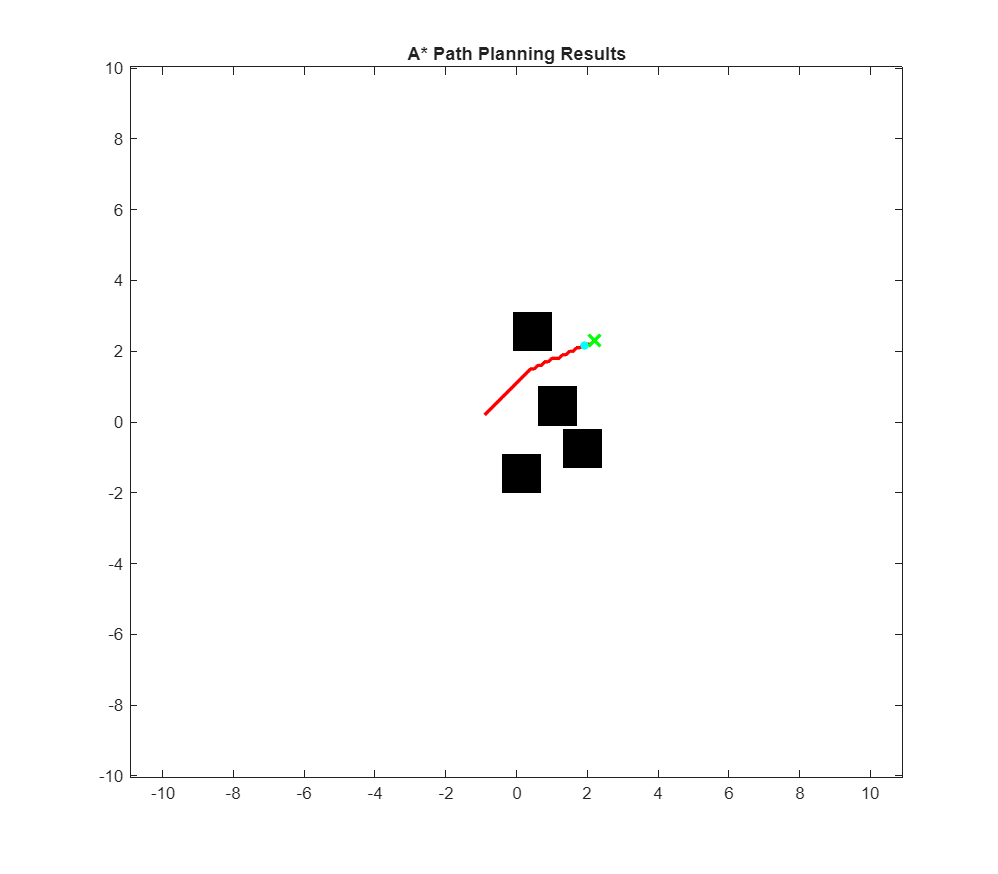

MISSION SUCCESS: GOAL REACHED!


Mission Finished.


system(['start "" "' exePath '"']);
pause(4); 

client = RemoteAPIClient();
sim = client.getObject('sim');

%% 2. LOAD SCENE
try
    disp('Cleaning up previous session...');
    sim.stopSimulation();
    while sim.getSimulationState() ~= sim.simulation_stopped, pause(0.1); end
    
    disp(['Loading Scene: ' sceneFile]);
    if isfile(sceneFile), sim.loadScene(sceneFile); end
    pause(1);

    % Handles
    robot  = sim.getObject('/summit_xl');
    goal   = sim.getObject('/Goal'); 
    
    % Wheel Handles (Robust Check)
    try
        wheels = [sim.getObject('/summit_xl_front_left_wheel'), ...
                  sim.getObject('/summit_xl_front_right_wheel'), ...
                  sim.getObject('/back_left_wheel'), ...
                  sim.getObject('/back_right_wheel')];
    catch
        wheels = [sim.getObject('/summit_xl/front_left_wheel_joint'), ...
                  sim.getObject('/summit_xl/front_right_wheel_joint'), ...
                  sim.getObject('/summit_xl/back_left_wheel_joint'), ...
                  sim.getObject('/summit_xl/back_right_wheel_joint')];
    end

    %% 3. GEOMETRY MAPPING
    disp('Generating Map from Object Coordinates...');
    
    mapSize = 20;        
    mapRes  = 0.1;       
    gridN   = round(mapSize / mapRes);
    
    occupancyGrid = true(gridN, gridN); 
    targetNames = {'Cuboid', 'Cylinder'};
    scanLimit = 20; 
    
    for t = 1:length(targetNames)
        baseName = targetNames{t};
        for k = 0:scanLimit
            if k == -1, objName = ['/' baseName];
            else, objName = sprintf('/%s[%d]', baseName, k); end
            try
                hObj = sim.getObject(objName);
                pos = sim.getObjectPosition(hObj, -1);
                if iscell(pos), pos = cell2mat(pos); end
                x = pos(1); y = pos(2);
                c = round((x + mapSize/2) / mapRes);
                r = round((y + mapSize/2) / mapRes);
                
                % INFLATION: 0.5m radius
                radius = 5; 
                r_start = max(1, r - radius); r_end = min(gridN, r + radius);
                c_start = max(1, c - radius); c_end = min(gridN, c + radius);
                occupancyGrid(r_start:r_end, c_start:c_end) = false;
            catch
                continue;
            end
        end
    end

    %% 4. A* PATH PLANNING
    disp('Planning Path (A*)...');
    
    rPos = sim.getObjectPosition(robot, -1);
    gPos = sim.getObjectPosition(goal, -1);
    if iscell(rPos), rPos=cell2mat(rPos); end
    if iscell(gPos), gPos=cell2mat(gPos); end
    
    startNode = world2grid(rPos(1), rPos(2), mapSize, mapRes);
    goalNode  = world2grid(gPos(1), gPos(2), mapSize, mapRes);
    
    pathIdx = a_star(occupancyGrid, startNode, goalNode);
    
    if isempty(pathIdx)
        error('No path found! Check obstacles.');
    end
    
    [pathR, pathC] = ind2sub(size(occupancyGrid), pathIdx);
    pathWorld = grid2world(pathR, pathC, mapSize, mapRes);

    % =============================================================
    % FORCE EXTERNAL PLOT WINDOW
    % =============================================================
    set(0, 'DefaultFigureWindowStyle', 'normal'); 
    f = figure('Name', 'Summit-XL Navigation Plan', ...
               'WindowStyle', 'normal', ... 
               'Color', 'w', ...
               'Position', [100, 100, 800, 700]);
    set(f, 'Visible', 'on');
    
    imagesc([-mapSize/2 mapSize/2], [-mapSize/2 mapSize/2], occupancyGrid);
    colormap gray; hold on; axis equal; set(gca, 'YDir', 'normal');
    plot(pathWorld(:,1), pathWorld(:,2), 'r-', 'LineWidth', 2);
    title('A* Path Planning Results');
    shg; drawnow;

    %% 5. NAVIGATION (EXACT PID)
    disp('Starting Navigation...');
    sim.setStepping(true);
    sim.startSimulation();
    
    % --- SUMMIT XL PARAMETERS ---
    v_lin = 0.1;          
    d = 0.73485;          
    r_wheel = 0.117345;   
    
    % --- PID GAINS ---
    Kp = 0.250; Ki = 0.0002; Kd = 0.001;
    LastError = 0; Integral = 0;
    
    currIdx = 1;
    lookahead = 0.6; 
    
    hRob = plot(rPos(1), rPos(2), 'c.', 'MarkerSize', 15);
    hTarget = plot(rPos(1), rPos(2), 'gx', 'MarkerSize', 10, 'LineWidth', 2);
    
    while ishandle(f)
        % 1. Get Robot Global State
        p = sim.getObjectPosition(robot, -1);
        if iscell(p), p=cell2mat(p); end
        
        % Update Visualization
        set(hRob, 'XData', p(1), 'YData', p(2)); 
        
        % 2. Check Goal Distance
        distToGoal = norm([p(1)-gPos(1), p(2)-gPos(2)]);
        if distToGoal < 0.3
            disp('MISSION SUCCESS: GOAL REACHED!');
            break;
        end
        
        % 3. Lookahead Selection
        while currIdx < size(pathWorld, 1)
            pt = pathWorld(currIdx, :);
            if norm([p(1)-pt(1), p(2)-pt(2)]) > lookahead
                break;
            end
            currIdx = currIdx + 1;
        end
        targetPt = pathWorld(currIdx, :);
        set(hTarget, 'XData', targetPt(1), 'YData', targetPt(2));
        drawnow limitrate;
        
        % 4. MATRIX FIX: Calculate Relative Position
        m = sim.getObjectMatrix(robot, -1);
        if iscell(m), m = cell2mat(m); end
        robotM = [reshape(m, [4, 3])'; 0 0 0 1];
        invRobM = inv(robotM);
        
        tWorld = [targetPt(1); targetPt(2); p(3); 1];
        tRel = invRobM * tWorld; 
        
        % 5. PID Calculation
        angle_error = atan2(tRel(2), tRel(1));
        
        DT = 0.05; 
        Derivative = (angle_error - LastError) / DT;
        Integral = Integral + (angle_error * DT);
        
        omega_robot = (Kp * angle_error) + (Kd * Derivative) + (Ki * Integral);
        
        LastError = angle_error;
        
        % 6. Compute Wheel Velocities
        v_right_lin = v_lin + (0.5 * d) * omega_robot;
        v_left_lin  = v_lin - (0.5 * d) * omega_robot;
        
        w_right = v_right_lin / r_wheel;
        w_left  = v_left_lin  / r_wheel;
        
        % 7. Actuate
        sim.setJointTargetVelocity(wheels(1), w_left);   
        sim.setJointTargetVelocity(wheels(3), w_left);   
        sim.setJointTargetVelocity(wheels(2), -w_right); 
        sim.setJointTargetVelocity(wheels(4), -w_right); 
        
        sim.step();
    end
    
    sim.stopSimulation();
    disp('Mission Finished.');
    
catch ME
    warning('Error: %s', ME.message);
    if exist('sim','var'), sim.stopSimulation(); end
end


%% HELPERS
function pathIdx = a_star(gridMap, startNode, goalNode)
    [rows, cols] = size(gridMap);
    [X, Y] = meshgrid(1:cols, 1:rows);
    [gr, gc] = ind2sub([rows, cols], goalNode);
    H = sqrt((X - gc).^2 + (Y - gr).^2);
    
    gScore = inf(rows, cols); gScore(startNode) = 0;
    fScore = inf(rows, cols); fScore(startNode) = H(startNode);
    cameFrom = zeros(rows, cols);
    openSet = [fScore(startNode), startNode];
    closedSet = false(rows, cols);
    pathIdx = [];
    
    while ~isempty(openSet)
        [~, minIdx] = min(openSet(:, 1));
        current = openSet(minIdx, 2);
        openSet(minIdx, :) = [];
        if current == goalNode
            pathIdx = current;
            while cameFrom(current) ~= 0
                current = cameFrom(current);
                pathIdx = [current; pathIdx]; %#ok<AGROW>
            end
            return;
        end
        closedSet(current) = true;
        [cr, cc] = ind2sub([rows, cols], current);
        neighbors = [cr-1, cc; cr+1, cc; cr, cc-1; cr, cc+1; cr-1, cc-1; cr-1, cc+1; cr+1, cc-1; cr+1, cc+1];
        for i = 1:8
            nr = neighbors(i, 1); nc = neighbors(i, 2);
            if nr>0 && nr<=rows && nc>0 && nc<=cols && gridMap(nr, nc) && ~closedSet(nr, nc)
                t_g = gScore(current) + norm([nr-cr, nc-cc]);
                nIdx = sub2ind([rows, cols], nr, nc);
                if t_g < gScore(nIdx)
                    cameFrom(nIdx) = current;
                    gScore(nIdx) = t_g;
                    fScore(nIdx) = t_g + H(nIdx);
                    if ~ismember(nIdx, openSet(:,2))
                        openSet = [openSet; fScore(nIdx), nIdx]; %#ok<AGROW>
                    else
                        openSet(openSet(:,2)==nIdx, 1) = fScore(nIdx);
                    end
                end
            end
        end
    end
end
function idx = world2grid(x, y, mapSize, res)
    c = max(1, min(round((x + mapSize/2) / res), round(mapSize/res)));
    r = max(1, min(round((y + mapSize/2) / res), round(mapSize/res)));
    idx = sub2ind([round(mapSize/res), round(mapSize/res)], r, c);
end
function world = grid2world(r, c, mapSize, res)
    world = [(c * res) - mapSize/2, (r * res) - mapSize/2];
end

**D* algorithm: **The D* algorithm is an incremental replanning version of A*. *Incremental* means that the algorithm reuses previous search effort instead of recomputing an entirely new plan whenever the environment changes. This makes D* particularly well suited for mobile robots operating in partially known or dynamic environments. D* updates only the nodes affected by the modifications in the map. A key characteristic of D* is that the search is usually reversed, it begins from the goal node and propagates cost information backward. This ensures that large portions of the previously computed solution remain valid and do not need to be recomputed.

# Randomized graph search

In many complex, high-dimensional path-planning problems—such as manipulation with multi-jointed robot arms, molecular folding, protein docking, or other continuous configuration-space tasks, it becomes computationally infeasible to search the space exhaustively within practical time limits. Traditional heuristic search is often ineffective in these domains because:

- suitable heuristic functions may be unavailable or extremely difficult to design, and

- dimensionality reduction techniques typically fail, especially when the robot must respect dynamic, velocity, and acceleration constraints that cannot be violated for safety or feasibility.

In such cases, randomized search methods provide a powerful alternative. These methods sacrifice guaranteed optimality in exchange for dramatically improved scalability and computational efficiency. Instead of exploring the entire space systematically, they sample configurations randomly and build a structure (such as a tree or graph) that probabilistically converges toward a valid solution.

Randomized methods are particularly attractive because they:

- scale well to high-dimensional configuration spaces,

- handle complex motion constraints,

- avoid the need for carefully crafted heuristics, and

- offer probabilistic completeness**, **they will find a solution with probability approaching 1 as time increases, provided a solution exists.

**Rapidly-Exploring Random Trees (RRTs):** Rapidly-Exploring Random Trees (RRTs) grow a search tree incrementally and online, requiring only an obstacle map rather than a precomputed graph or decomposition. The algorithm begins with an initial tree rooted at the start configuration (or even an empty seed) and successively expands this tree until a termination condition is met, such as reaching the goal or hitting a time limit.

At each iteration:

- A random configuration $q_{\text{rand}}$ is sampled from the free space.

- The nearest existing node in the tree, $q_{\text{rand}}$, is found using a suitable metric.

- A new configuration $q_{\text{new}}
$ is generated by moving from $q_{\text{near}}$ towards $q_{\text{rand}}$, typically by a fixed step size and using an appropriate robot motion model.

- If the path between $q_{\text{near}}$ and $q_{\text{new}}$ is collision-free, the new configuration is added to the tree as a new node.

This process tends to rapidly push the tree outward into unexplored regions of the configuration space, hence the name.

# Potential field path planning

Potential field path planning constructs a scalar field (an artificial potential) over the robot’s map that guides the robot toward the goal while pushing it away from obstacles. In this method, the robot is treated as a point subject to an artificial potential function $U\left(q\right)\ldotp$ The robot moves by following the negative gradient of this potential, much like a ball rolling downhill. The goal forms a minimum (attractive basin), while obstacles form peaks (repulsive regions). The sum of these influences produces a smooth field that directs the robot toward the goal while avoiding known obstacles.

The robot is attracted to the goal and repelled from obstacles. If new obstacles appear, their effect can be incorporated by updating the potential field. For simplicity, we treat the robot as a point and ignore orientation, making the potential field a function of planar position $q=(x,y)$. If the potential function $U\left(q\right)$ is differentiable, the artificial force acting on the robot is given by $F(q) = - \nabla U(q),
$ where $\nabla U(q)$ is the gradient of the potential at configuration $q$. The potential is typically decomposed into attractive and repulsive components  $U(q) = U_{\text{att}}(q) + U_{\text{rep}}(q),$ and correspondingly, $F(q) = F_{\text{att}}(q) + F_{\text{rep}}(q). $ A common form of attractive potential is the parabolic model $U_{\text{att}}(q) = \frac{1}{2} k_{\text{att}} \, p_{\text{goal}}(q)^2$, where $k
_att
	

>0 \text{ is a scaling constant,}$ $p_{\text{goal}}$ is the Euclidean distance to the goal. The corresponding attractive force $F_{\text{att}}(q) = - \nabla U_{\text{att}}(q) = -k_{\text{att}} \, p_{\text{goal}}(q)\, \nabla p_{\text{goal}}(q)
$. This force smoothly decreases to zero as the robot approaches the goal. The repulsive potential prevents the robot from approaching obstacles too closely. It is designed to be strong near obstacles but negligible far away. A common formulation is given by $U_{\text{rep}}(q) = \begin{cases} \displaystyle \frac{1}{2} k_{\text{rep}} \left( \frac{1}{p(q)} - \frac{1}{p_0} \right)^2, & \text{if } p(q) \le p_0, \\[10pt] 0, & \text{if } p(q) > p_0, \end{cases}$ where $ k_{rep}>0$ is a scaling factor, $p\left(q\right)$ is the minimum distance from $q$ to any obstacle, and $p_0$� defines the obstacle’s influence radius. The repulsive force becomes  $F_{\text{rep}}(q) = \begin{cases} k_{\text{rep}} \left(\frac{1}{p(q)} - \frac{1}{p_0}\right) \frac{1}{p(q)^2} \nabla p(q), & \text{if } p(q) \le p_0,\\[10pt] 0, & \text{if } p(q) > p_0, \end{cases}$  pushing the robot away from obstacles. The total force is given by $F(q) = F_{\text{att}}(q) + F_{\text{rep}}(q)
$.

While intuitive and computationally efficient, potential fields have two major drawbacks:

- **Local minima: **The combined potential may contain points other than the goal where the gradient becomes zero. The robot can get stuck at these locations.

- **Concave obstacles: **For nonconvex shapes, multiple nearest-obstacle points may exist, leading to oscillations or unstable behavior.

These issues compromise **completeness** and are a well-known weakness of basic potential field methods.

## Try Yourself: Potential Field Navigation 

This example shows how a robot plans motion using a **potential field method**.

Instead of searching for a path explicitly, the robot moves under the influence of **virtual forces**:

- attraction toward the goal 

- repulsion away from obstacles 

##  What the Code Does

At each step, the robot computes forces and updates its position.

** 1. Attractive Force (Goal Seeking)**

The robot is pulled toward the goal:

`F_att = k_att * (goal - pos)`

- Points directly to the goal 

- Strength depends on distance 

 This ensures the robot keeps moving toward the target.

**2. Repulsive Force (Obstacle Avoidance)**

Each obstacle pushes the robot away:

`F_rep ∝ (pos - obs)`

- Only active within a distance `d0`

- Stronger when the robot is closer to the obstacle 

This prevents collisions.

** 3. Total Force**

`F = F_att + F_rep`

- Combines goal attraction and obstacle avoidance 

- The robot moves in the direction of this force 

**4. Motion Update**

`pos = pos + step_size * normalized(F)`

- Direction comes from force 

- Step size controls speed 

** 5. Potential Field (Right Plot)**

The contour plot shows the **energy landscape**:

- Goal → low potential (valley) 

- Obstacles → high potential (peaks) 

The robot moves “downhill” in this landscape.

** What to Observe****Left Plot (Motion)**

- Shows actual robot movement 

- Path curves around obstacles 

**Right Plot (Contours)**

- Shows why the robot moves that way 

- Dense contours → strong forces 

**Force Vector**

- Arrow shows direction of motion 

- Always points toward lower potential 

## What You Can Tune

1. Obstacles (`obs`**)**

- Change number and position 

- Create narrow passages or walls 

**2. Attraction (**`k_att`**)**

- High → aggressive motion toward goal 

- Low → slower movement 

**3. Repulsion (**`k_rep`**)**

- High → strong avoidance (may oscillate) 

- Low → weak avoidance (risk of collision) 

**4. Influence Distance (**`d0`**)**

- Large → early avoidance 

- Small → late avoidance 

**5. Step Size (**`step_size`**)**

- Large → fast but unstable 

- Small → smooth but slow 

## Important Design Detail

Repulsion is reduced near the goal:

`scale = min(1, goal_dist/5)`

 Without this:

- robot may never reach the goal 

- gets pushed away near the target 

%% 🌊 Task: Potential Field (Motion + Contour Visualization)

pos = [2 2];        
% 👉 Initial robot position
% Try changing start location (e.g., [5 5], [1 18])

goal = [18 18];     
% 👉 Goal position
% Move goal to see different paths

% ===== 🔧 MULTIPLE OBSTACLES (EDIT THIS) =====
obs = [10 10;
       12 14;
       6  12];   
% 👉 Add/remove obstacles or create walls
% Example:
% obs = [8 10; 9 10; 10 10; 11 10; 12 10];  % vertical wall

% ===== 🔧 PARAMETERS TO TUNE =====
k_att = 0.05;    
% 👉 Attraction strength toward goal
% High → faster, aggressive motion
% Low → slow movement

k_rep = 8;       
% 👉 Repulsion strength from obstacles
% High → strong avoidance (may oscillate)
% Low → may collide with obstacles

d0 = 5;          
% 👉 Influence distance of obstacles
% Large → obstacles affect robot earlier
% Small → robot reacts late

step_size = 0.3;
% 👉 How far robot moves per step
% Large → faster but unstable
% Small → smooth but slow

% =====================================================

[X,Y] = meshgrid(1:20,1:20);

figure


for t = 1:150
    
    clf   % clear figure each frame
    
    %% ===== FORCE COMPUTATION =====
    
    % --- Attractive force (toward goal) ---
    F_att = k_att*(goal - pos);
    
    % --- Repulsive force (from all obstacles) ---
    F_rep = [0 0];
    
    for i = 1:size(obs,1)
        d = norm(pos - obs(i,:));
        
        if d < d0   % only nearby obstacles affect robot
            
            % 👉 Reduce repulsion near goal (important!)
            goal_dist = norm(pos - goal);
            scale = min(1, goal_dist/5);
            
            F_rep = F_rep + scale * ...
                k_rep*(pos - obs(i,:))*(1/d - 1/d0)/(d^3 + 0.1);
        end
    end
    
    % --- Total force ---
    F = F_att + F_rep;
    
    % --- Motion update (normalized for stability) ---
    pos = pos + step_size * F / (norm(F)+1e-6);
    
    %% ===== STOP CONDITION =====
    if norm(pos - goal) < 0.5
        break
    end
    
    %% ===== SUBPLOT 1: ROBOT MOTION =====
    subplot(1,2,1)
    
    plot(goal(1),goal(2),'gx','LineWidth',2); hold on
    plot(obs(:,1),obs(:,2),'ro','MarkerFaceColor','r')
    plot(pos(1),pos(2),'bo','MarkerFaceColor','b')
    
    xlim([0 20]); ylim([0 20])
    title('Robot Motion')
    grid on
    
    %% ===== SUBPLOT 2: POTENTIAL FIELD =====
    subplot(1,2,2)
    
    % --- Compute potential field ---
    U = k_att*((X-goal(1)).^2 + (Y-goal(2)).^2);
    
    for i = 1:size(obs,1)
        d = sqrt((X-obs(i,1)).^2 + (Y-obs(i,2)).^2);
        mask = d < d0;
        
        U(mask) = U(mask) + k_rep*(1./d(mask) - 1/d0).^2;
    end
    
    contour(X,Y,U,20); hold on
    
    % --- Draw elements ---
    plot(goal(1),goal(2),'gx','LineWidth',2)
    plot(obs(:,1),obs(:,2),'ro','MarkerFaceColor','r')
    plot(pos(1),pos(2),'bo','MarkerFaceColor','b')
    
    % --- Show force direction ---
    quiver(pos(1),pos(2),F(1),F(2),0,'k','LineWidth',2)
    
    xlim([0 20]); ylim([0 20])
    title('Potential Field (Contours + Force)')
    grid on
    
    pause(0.05)
end

# Obstacle avoidance

Local obstacle avoidance concerns the real-time modification of a robot’s trajectory based on its sensor observations during motion. The robot’s resulting behavior depends on two factors:

- **Current (or recent) sensor readings**, which indicate nearby obstacles, and

- **The relative position of the goal**, which provides a general direction of desired motion.

The obstacle-avoidance methods presented in this section differ in their assumptions about the availability of a global map and the robot’s localization accuracy. However, they are all considered obstacle-avoidance algorithms because local sensor information plays a central role in determining the robot’s immediate trajectory.

**Bug algorithms: **The Bug algorithms are among the simplest possible methods for local obstacle avoidance. Their core idea is intuitive, "**When the robot encounters an obstacle, it follows the obstacle’s boundary until it can resume motion toward the goal." **Despite their simplicity  and sometimes extreme inefficiency, Bug algorithms possess strong theoretical guarantees that they will reach the goal whenever a path exists. 

## Bug 1

In Bug 1, when the robot meets an obstacle, it fully circumnavigates the obstacle’s boundary once. While doing so, it monitors the point on the boundary that is closest to the goal. After completing the loop, the robot returns to that point and departs toward the goal. This strategy guarantees completeness but is often highly inefficient, since the robot must trace the entire perimeter of every encountered obstacle.

## Bug 2

Bug 2 achieves better performance in many cases. Upon hitting an obstacle, the robot begins following the obstacle’s boundary (wall-following). However, it does not complete a full loop. Instead, it leaves the boundary as soon as it finds a point from which it can move straight toward the goal without immediate collision.

This results in significantly shorter travel distances compared to Bug 1. Nevertheless, contrived environments can still cause arbitrarily inefficient motions, so Bug 2 remains suboptimal.

## TangentBug

A more advanced variant is TangentBug, which enhances efficiency by using range-sensor information to construct a local tangent graph (LTG). With the LTG, the robot can:

- choose more informed directions during boundary following,

- take shortcuts along tangential directions, and

- switch back to goal-seeking earlier when safe.

In many simple environments, TangentBug can closely approach globally optimal paths, significantly outperforming the simpler Bug methods.

**Vector Field Histogram (VFH): **A major weakness of Bug-type obstacle avoidance methods is that they base decisions solely on instantaneous sensor readings. This makes them vulnerable in situations where the robot's immediate sensor data does not reveal enough information for robust motion decisions. VFH overcomes this limitation by constructing and updating a local occupancy grid,a small robot-centered map derived from recent sensor readings. From this local occupancy grid, VFH computes a **polar histogram**, in which the x-axis represents direction (angle $\alpha $) relative to the robot, the y-axis represents the probability $P$ of an obstacle in that direction, as inferred from the local occupancy grid. Using this histogram, the algorithm identifies steering directions that avoid obstacles while keeping the robot oriented toward the goal. The VFH algorithm proceeds in two stages:

- **Identify feasible openings** in the polar histogram, continuous angular sectors where the robot can physically pass.

- **Evaluate each opening** using a cost function and choose the opening with the lowest cost.

The cost function $G$ is given by $G = a \cdot \text{target\_direction} + b \cdot \text{wheel\_orientation} + c \cdot \text{previous\_direction}$, where

- **target_direction** measures alignment with the direction to the goal,

- **wheel_orientation** is the angular difference between the candidate steering direction and the robot’s current wheel heading,

- **previous_direction** penalizes sharp deviations from the last chosen direction (encouraging smooth motion).

- The parameters $a,b,c$ adjust the robot’s behavior. 

**The bubble band technique: **A bubble is defined as the largest local region of free space surrounding a given robot configuration within which the robot can move without collision. The bubble is computed using a simplified geometric model of the robot together with range information from the robot’s map. Even with simple geometric approximations, the bubble’s shape can reflect the robot’s actual physical dimensions and orientation. Once individual bubbles are computed, they are arranged along the robot’s planned path, forming a bubble band, a connected sequence of overlapping bubbles extending from the start to the goal. Constructing a bubble band requires both:

- a global map, and

- a global path planner to provide an initial trajectory.

After the initial path is obtained, the bubble band is generated, and the trajectory is then adjusted based on two kinds of forces:

- **External forces** originating from obstacles in the environment (as represented by the free-space geometry), and

- **Internal forces** that act like tension in a string, attempting to minimize slack between adjacent bubbles.

These forces iteratively deform the path so that the robot’s motion remains smooth and consistent with the available free space. A final smoothing stage ensures that the resulting path is dynamically feasible and varies smoothly as the robot progresses.

**Curvature velocity techniques (CVM): **CVM operates in velocity space, defined by:

- translational velocity $v$, and

- rotational velocity $\omega$.

For any pair $\left(v,\omega \right)$, the robot’s trajectory is assumed to be an arc of a circle with curvature $c = \frac{\omega}{v}$.

Thus, obstacle avoidance becomes the task of determining which pairs $\left(v,\omega \right)$ produce safe, feasible trajectories. Two broad categories of constraints define the admissible velocity space:

**(a) Robot constraints**

These arise from kinematic and dynamic limits: $v_{\min} < v < v_{\max}, \quad  \omega_{\min} < \omega < \omega_{\max},$ along with limits on acceleration and deceleration.

**(b) Obstacle constraints**

Obstacles in the Cartesian map are projected into velocity space. For any candidate curvature $c$, the distance from the robot to an obstacle along the corresponding circular arc is computed. If the robot would collide with the obstacle at that curvature, then the corresponding $\left(v,\omega \right)$ pair is forbidden. Only curvatures in the range $[c_{\min}, c_{\max}]$ need to be evaluated, since this interval contains all physically feasible robot trajectories.

To achieve **real-time performance**, CVM uses several approximations:

- Obstacles are modeled as circles.

- Each obstacle contour is discretized into a small number of angular intervals.

- Between interval endpoints, the distance-to-collision is treated as constant.

The robot evaluates candidate velocities only within the subset of velocity space that is:

- kinematically feasible,

- dynamically allowed, and

- obstacle-free.

An objective function then selects the optimal velocity pair $\left(v,\omega \right)$, balancing safety, progress toward the goal, and smoothness. A key advantage of CVM is that it naturally incorporates vehicle dynamics. However, the circular-obstacle approximation can be problematic in cluttered environments with elongated or non-uniform obstacles. Moreover, because CVM relies solely on instantaneous sensor data and no global knowledge, it may suffer from local minima. 

**Lane Curvature Method (LCM):  **In CVM the assumption that the robot moves along a single, fixed arc is overly restrictive. LCM takes a more flexible approach than CVM by computing a set of candidate lanes:

- Each lane is a feasible path corridor extending forward from the robot.

- Lane quality depends on both length (how far the robot can proceed) and width (distance to nearby obstacles).

The algorithm then evaluates all lanes using a cost function and selects the **best lane**, typically the one offering the safest and most promising passage forward. By considering multiple forward-looking motion corridors rather than a single curvature arc, LCM improves robustness in structured indoor environments, particularly in places where CVM tends to get stuck, such as corridor intersections and doorways. 

**Dynamic Window Approaches: **Another effective technique for incorporating the robot’s kinematic and dynamic constraints into obstacle avoidance is the dynamic window approach. This method relies on a simple but powerful dynamic model of the robot, from which it takes its name. Two major versions exist:

- the **local Dynamic Window Approach (DWA)** 

- the **Global Dynamic Window Approach (GDWA)**

Both methods operate in velocity space, directly evaluating feasible translational and rotational velocities rather than explicitly planning geometric paths.

 **Local Dynamic Window Approach: **In the local DWA, the robot’s motion is represented by circular arcs, each defined by a pair $\left(v,\omega \right)$, where:

- $v$ = translational velocity

- $\omega$ = angular velocity

The algorithm proceeds in three stages:

**(a) Constructing the dynamic window**

Given the robot’s current velocity and its acceleration limits, the dynamic window consists of all velocity pairs $\left(v,\omega \right)$ that the robot can achieve within the next control cycle. This window reflects the robot’s physical acceleration constraints.Because translational and rotational accelerations are treated as independent, the dynamic window has a rectangular shape in $\left(v,\omega \right)$-space.

**(b) Selecting admissible velocities**

Next, velocities that would inevitably lead to a collision are removed. A velocity pair $\left(v,\omega \right)$ is considered admissible only if the robot can brake to a stop before hitting an obstacle along the associated circular trajectory. This ensures collision-free motion, even at high speeds.

**(c) Selecting the optimal motion command**

An objective function evaluates all admissible velocities given by $O =  a \cdot \text{heading}(v, \omega) + b \cdot \text{velocity}(v, \omega) + c \cdot \text{dist}(v, \omega)$, where

- **heading**: measures alignment with the goal direction

- **velocity**: favors faster forward motion

- **dist**: maximizes clearance from nearby obstacles

The velocity pair that maximizes $O$ becomes the next command. This makes DWA fast, reactive, and physically feasible for nonholonomic robots.

% =============================================================
% PLANNING MISSION: DWA (TUNED TO FIX SPINNING)
% Integrated for Live Script & ZMQ API
% =============================================================
clc; clear; close all force;
disp('INITIALIZING DWA NAVIGATION...');

INITIALIZING DWA NAVIGATION...



%% 1. CONFIGURATION & SETUP
% --- Dynamic Path Configuration ---
coppeliaRoot = getenv('COPPELIA_ROOT');
if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found.');
end

apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');
addpath(apiPath);

% --- Scene Path ---
if matlab.desktop.editor.isEditorAvailable
    currentPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    currentPath = pwd;
end
sceneFile = fullfile(currentPath, 'scenes', 'planning scene.ttt');

% Launch CoppeliaSim
disp('Launching CoppeliaSim...');

Launching CoppeliaSim...


system(['start "" "' exePath '"']);
pause(4); 

client = RemoteAPIClient();
sim = client.getObject('sim');

%% 2. LOAD SCENE
try
    disp('Cleaning up previous session...');
    sim.stopSimulation();
    while sim.getSimulationState() ~= sim.simulation_stopped, pause(0.1); end
    
    disp(['Loading Scene: ' sceneFile]);
    if isfile(sceneFile), sim.loadScene(sceneFile); end
    pause(1);

    % Handles (Resilient Fetching)
    robot  = sim.getObject('/summit_xl');
    goal   = sim.getObject('/Goal'); 
    try
        wheels = [sim.getObject('/summit_xl_front_left_wheel'), ...
                  sim.getObject('/summit_xl_front_right_wheel'), ...
                  sim.getObject('/back_left_wheel'), ...
                  sim.getObject('/back_right_wheel')];
    catch
        wheels = [sim.getObject('/summit_xl/front_left_wheel_joint'), ...
                  sim.getObject('/summit_xl/front_right_wheel_joint'), ...
                  sim.getObject('/summit_xl/back_left_wheel_joint'), ...
                  sim.getObject('/summit_xl/back_right_wheel_joint')];
    end

    %% 3. GEOMETRY MAPPING
    disp('Generating Map for Obstacle Avoidance...');
    mapSize = 20; mapRes = 0.1; gridN = round(mapSize / mapRes);
    occupancyGrid = true(gridN, gridN); 
    targetNames = {'Cuboid', 'Cylinder'};
    
    for t = 1:length(targetNames)
        baseName = targetNames{t};
        for k = 0:20
            objName = sprintf('/%s[%d]', baseName, k);
            try
                hObj = sim.getObject(objName);
                pos = cell2mat(sim.getObjectPosition(hObj, -1));
                c = round((pos(1) + mapSize/2) / mapRes);
                r = round((pos(2) + mapSize/2) / mapRes);
                
                % DWA uses point obstacles, so we use light inflation
                radius = 2; 
                r_range = max(1, r-radius):min(gridN, r+radius);
                c_range = max(1, c-radius):min(gridN, c+radius);
                occupancyGrid(r_range, c_range) = false;
            catch, continue; end
        end
    end
    
    [obsR, obsC] = find(~occupancyGrid);
    obsList = grid_to_world_coords(obsR, obsC, mapSize, mapRes);

    %% 4. NAVIGATION LOOP (DWA)
    % =============================================================
    % FORCE EXTERNAL PLOT WINDOW
    % =============================================================
    set(0, 'DefaultFigureWindowStyle', 'normal'); 
    fig = figure('Name', 'DWA Local Planning', 'WindowStyle', 'normal', 'Color', 'w');
    set(fig, 'Visible', 'on');
    
    imagesc([-mapSize/2 mapSize/2], [-mapSize/2 mapSize/2], occupancyGrid);
    colormap gray; hold on; axis equal; set(gca, 'YDir', 'normal');
    
    rPos = cell2mat(sim.getObjectPosition(robot, -1));
    gPos = cell2mat(sim.getObjectPosition(goal, -1));
    hRob = plot(rPos(1), rPos(2), 'c.', 'MarkerSize', 20);
    plot(gPos(1), gPos(2), 'gx', 'MarkerSize', 12, 'LineWidth', 2);
    shg; drawnow;

    sim.setStepping(true);
    sim.startSimulation();
    
    % DWA Config
    dt = 0.05; max_speed = 0.6; max_yaw_rate = 40 * pi/180; 
    max_accel = 0.2; max_dyaw = 40 * pi/180; 
    weights = [0.1, 0.2, 1.0]; % [Heading, Distance, Velocity]
    config = [0.0, max_speed, max_yaw_rate, max_accel, max_dyaw, weights, 2.0, dt];

    % Kinematics
    L = 0.582; r_wheel = 0.165;
    state = [rPos(1); rPos(2); 0; 0; 0]; % [x, y, yaw, v, w]
    goal_pt = [gPos(1); gPos(2)];
    
    while ishandle(fig)
        pos = cell2mat(sim.getObjectPosition(robot, -1));
        ori = cell2mat(sim.getObjectOrientation(robot, -1));
        state(1:3) = [pos(1); pos(2); ori(3)];
        
        set(hRob, 'XData', state(1), 'YData', state(2)); drawnow limitrate;
        
        if norm(state(1:2) - goal_pt) < 0.3
            disp('Goal Reached!'); break;
        end
        
        [u, ~] = dwa_control(state, goal_pt, obsList, config);
        state(4:5) = u; % Update current v, w
        
        % Actuate
        wl = (u(1) - u(2)*L/2)/r_wheel;
        wr = (u(1) + u(2)*L/2)/r_wheel;
        sim.setJointTargetVelocity(wheels(1), wl);
        sim.setJointTargetVelocity(wheels(3), wl);
        sim.setJointTargetVelocity(wheels(2), -wr);
        sim.setJointTargetVelocity(wheels(4), -wr);
        
        sim.step();
    end
    sim.stopSimulation();

catch ME
    warning('Error: %s', ME.message);
    if exist('sim','var'), sim.stopSimulation(); end
end

Cleaning up previous session...


Loading Scene: C:\Users\prita\Desktop\Mathworks_1205\Planning\scenes\planning scene.ttt


Generating Map for Obstacle Avoidance...



%% ================= DWA HELPERS =================
function [u, best_traj] = dwa_control(x, goal, ob, config)
    dw = [max(config(1), x(4)-config(4)*config(10)), min(config(2), x(4)+config(4)*config(10)), ...
          max(-config(3), x(5)-config(5)*config(10)), min(config(3), x(5)+config(5)*config(10))];
    min_score = inf; best_u = [0, 0]; best_traj = [];
    
    for v = dw(1):0.05:dw(2)
        for w = dw(3):0.05:dw(4)
            traj = calc_trajectory(x, v, w, config(9), config(10));
            cost = config(6)*calc_to_goal_cost(traj, goal) + ...
                   config(8)*(config(2) - traj(end, 4)) + ...
                   config(7)*calc_obstacle_cost(traj, ob);
            if cost < min_score
                min_score = cost; best_u = [v, w]; best_traj = traj;
            end
        end
    end
    u = best_u;
    if best_u(1) == 0 && best_u(2) == 0, u = [0, -0.2]; end
end

function traj = calc_trajectory(x, v, w, predict_time, dt)
    traj = x'; curr = x;
    for t = 0:dt:predict_time
        curr(1) = curr(1) + v * cos(curr(3)) * dt;
        curr(2) = curr(2) + v * sin(curr(3)) * dt;
        curr(3) = curr(3) + w * dt;
        traj = [traj; curr']; %#ok<AGROW>
    end
end

function cost = calc_to_goal_cost(traj, goal)
    error_angle = atan2(goal(2)-traj(end,2), goal(1)-traj(end,1));
    cost = abs(atan2(sin(error_angle - traj(end,3)), cos(error_angle - traj(end,3))));
end

function cost = calc_obstacle_cost(traj, ob)
    min_r = min(sqrt((ob(:,1)-traj(:,1)').^2 + (ob(:,2)-traj(:,2)').^2), [], 'all');
    if min_r < 0.35, cost = inf; else, cost = 1.0 / min_r; end
end

function world = grid_to_world_coords(r, c, mapSize, res)
    world = [(c * res) - mapSize/2, (r * res) - mapSize/2];
end

**Global Dynamic Window Approach (GDWA): **While the local DWA uses only local sensor data, the global dynamic window approach incorporates global planning information into the velocity evaluation. This is done by integrating an NF1 (wavefront) transform, sometimes called grassfire. The NF1 algorithm assigns each cell in the occupancy grid a cost equal to its distance from the goal. To maintain computational efficiency, NF1 is computed only over a rectangular region ahead of the robot:

- The region is directed toward the goal.

- It is expanded if the goal is not reachable within the current bounds.

This adds a “global bias” to the dynamic window, allowing the robot to:

- move with high speed,

- obey dynamic constraints,

- avoid local minima, and

- incorporate updated obstacle information as the occupancy grid evolves.

If NF1 fails (e.g., when the robot is completely surrounded), GDWA automatically falls back to local DWA, ensuring that the robot keeps moving and can potentially break out of confined spaces.

# **Quiz**

1.Why is 'completeness' a critical property for evaluating robot path planning algorithms?

"It guarantees that if a solution exists, the algorithm will find it; otherwise, it reports failure."

ans = "It guarantees that if a solution exists, the algorithm will find it; otherwise, it reports failure."

switch ans
    case "It guarantees that if a solution exists, the algorithm will find it; otherwise, it reports failure."
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

Right Answer


2. In the context of Potential Field methods, what is a 'Local Minimum'?

"A location other than the goal where the attractive and repulsive forces cancel out to zero."

ans = "A location other than the goal where the attractive and repulsive forces cancel out to zero."

switch ans
    case "A location other than the goal where the attractive and repulsive forces cancel out to zero."
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

Right Answer


3. Which statement correctly describes the difference between Dijkstra’s Algorithm and A*?

"A* uses a heuristic to estimate the cost-to-goal, guiding the search more efficiently."

ans = "A* uses a heuristic to estimate the cost-to-goal, guiding the search more efficiently."

switch ans
    case "A* uses a heuristic to estimate the cost-to-goal, guiding the search more efficiently."
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

Right Answer


# **Exercise**

**1) **A large floor (10m $\times$ 10m). A differential-drive robot. Several static obstacles (walls or cylinders) creating a "U-shape" trap or a cluttered field

2) Make a binary occupancy grid map of the environment where $$0=$ Free and $1=$$ Occupied.

3) Write a MATLAB script to implement the *A Search Algorithm**.

4) Plot the grid map. Overlay the calculated path in Red.

5) Bring some moving actors (humans) in the scene and Dynamic Window Approach to avoid collision.